clc,clear,close all;


dataDir = 'D:\matlabProject\Stock\data';
dataPath = fullfile(dataDir,'000001.csv')

dataPath = 'D:\matlabProject\Stock\data\000001.csv'

dataTable = readtable(dataPath);

% CELL test 
cell1 = {'data',dataTable.x__;'percent',dataTable.x____7};
cell2 = {dataTable.x__;dataTable.x____7};

Refer to sets of cells by enclosing indices in smooth parentheses, (). Access the contents of cells by indexing with curly braces, {}.

% CELL using
cell1(1,:)

ans = 1×2 cell 数组
    {'data'}    {7179×1 datetime}


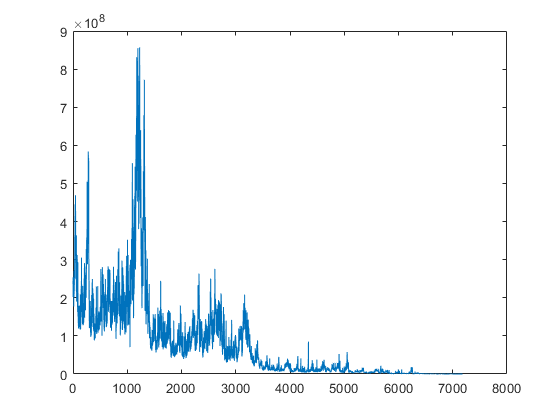

temp = cell2mat(cell1(2,2));
figure()
plot(temp);


figure()
plot(cell1{2,2})

% STRUCT test
struct1 = struct('date',dataTable.x__,'percent',dataTable.x____7)

struct1 = 包含以下字段的 struct :
       date: [7179×1 datetime]
    percent: [7179×1 double]


struct1.anotherStruct = struct('data1',0,'data2',0,'data3',0)

struct1 = 包含以下字段的 struct :
             date: [7179×1 datetime]
          percent: [7179×1 double]
    anotherStruct: [1×1 struct]


for i = 1:10
    temp_string_num = int2str(i);
    temp_string =['son',temp_string_num];
    struct1.anotherStruct.dataMom(i).data=i;
    struct1.anotherStruct.dataMom(i).size=zeros(1,i);
end
struct1.anotherStruct.dataFather.data.size =1

struct1 = 包含以下字段的 struct :
             date: [7179×1 datetime]
          percent: [7179×1 double]
    anotherStruct: [1×1 struct]


testEmpty =struct('obj1',[],'obj2',1);
if testEmpty.obj2
    disp('1');
else
    disp('0');
end

1


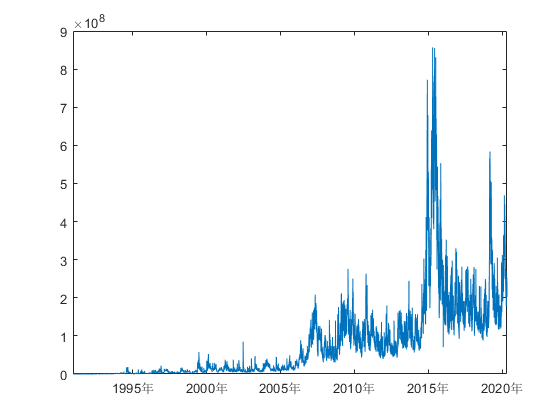

% STRUCT using
figure()
plot(struct1.date,struct1.percent);